# chapter 10: signal detection theory

figure
hold on
x = 0:0.1:10;
% firing rate of a neuron in the absence of a visual stimulus
y = normpdf(x, 5, 1.5)

y =     0.0010    0.0013    0.0016    0.0020    0.0024    0.0030    0.0036    0.0044    0.0053    0.0063    0.0076    0.0091    0.0107    0.0127    0.0149    0.0175    0.0204    0.0236    0.0273    0.0314    0.0360    0.0410    0.0466    0.0526    0.0592    0.0663    0.0739    0.0821    0.0907    0.0998    0.1093    0.1192    0.1295    0.1399    0.1506    0.1613    0.1721    0.1827    0.1931    0.2033    0.2130    0.2221    0.2307    0.2385    0.2455    0.2516    0.2567    0.2607    0.2636    0.2654


plot(x,y)
% firing rate of a neuron in response to a visual stimulus
z = normpdf(x, 6, 1.5)

z =     0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0013    0.0016    0.0020    0.0024    0.0030    0.0036    0.0044    0.0053    0.0063    0.0076    0.0091    0.0107    0.0127    0.0149    0.0175    0.0204    0.0236    0.0273    0.0314    0.0360    0.0410    0.0466    0.0526    0.0592    0.0663    0.0739    0.0821    0.0907    0.0998    0.1093    0.1192    0.1295    0.1399    0.1506    0.1613    0.1721    0.1827    0.1931    0.2033


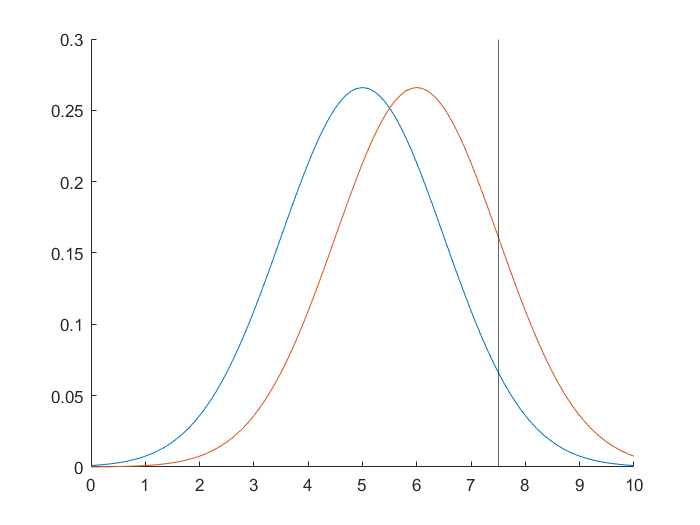

plot(x,z)
% criterion level: 7.5 = mu + sigma
% 1, firing rate > 7.5 (stimulus present)
% 0, firing rate < 7.5 (no stimulus)
xline(7.5)

## reciever operating characteristic (ROC)

$\text{TPR} =\frac{\text{TP}}{\text{P}} =  \frac{\text{TP}}{\text{TP}+ \text{FN}}$ (precision rate, sensitivity, or recall)

$\text{FPR} =\frac{\text{FP}}{\text{N}} =  \frac{\text{FP}}{\text{FP}+ \text{TN}}$ (fall-out)

$\text{TNR} =\frac{\text{TN}}{\text{N}}= \frac{\text{TN}}{\text{TN}+\text{FP}}$ (specifity)

$\text{FNR} =\frac{\text{FN}}{\text{T}}= \frac{\text{TN}}{\text{FN}+\text{TP}}$ (miss rate)

ROC curve: plot **FPR** against **TPR**

figure
FPR = flip(1 - cumsum(y)/10)

FPR =     0.0008    0.0009    0.0010    0.0011    0.0013    0.0016    0.0019    0.0022    0.0027    0.0032    0.0038    0.0046    0.0055    0.0066    0.0079    0.0093    0.0111    0.0131    0.0155    0.0182    0.0214    0.0250    0.0291    0.0337    0.0390    0.0449    0.0515    0.0589    0.0672    0.0762    0.0862    0.0971    0.1091    0.1220    0.1360    0.1511    0.1672    0.1844    0.2027    0.2220    0.2423    0.2636    0.2858    0.3089    0.3327    0.3573    0.3824    0.4081    0.4342    0.4605


TPR = flip(1 - cumsum(z)/10)

TPR =     0.0035    0.0042    0.0052    0.0062    0.0075    0.0090    0.0107    0.0128    0.0151    0.0179    0.0210    0.0246    0.0287    0.0334    0.0386    0.0446    0.0512    0.0586    0.0668    0.0759    0.0859    0.0968    0.1087    0.1217    0.1356    0.1507    0.1668    0.1840    0.2023    0.2216    0.2420    0.2632    0.2855    0.3085    0.3324    0.3569    0.3821    0.4078    0.4338    0.4602    0.4867    0.5133    0.5399    0.5662    0.5923    0.6180    0.6431    0.6677    0.6915    0.7146


plot(FPR, TPR)
hold on
random_guess = 0:0.1:1

random_guess =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


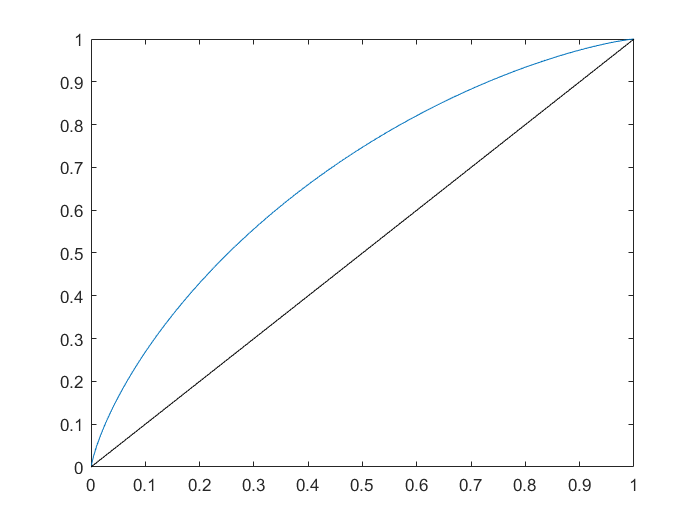

plot(random_guess, random_guess, 'Color','k')

### Discriminabily index (d'): 

It is defined as the distance between the means of the 2 distributions.

## Likelihood ratio

### GAME: guess cards value (table 10.3)

TP = (6:1:27).';
pc_ten = zeros(22,1);
pc_one = zeros(22,1);
lr = zeros(22,1);
table_3 = table(TP, pc_ten, pc_one, lr);
for i = [1,10]
    for j = 2:1:9
        for k = j+1:1:9
            t = i + j + k;
            if ~ismember(t, table_3.TP)
                continue;
            end
            if i == 1
                table_3.pc_one(find(table_3.TP == t)) = table_3.pc_one(find(table_3.TP == t)) + 1;
            else
                table_3.pc_ten(find(table_3.TP == t)) = table_3.pc_ten(find(table_3.TP == t)) + 1;
            end
        end
    end
end
table_3.lr = table_3.pc_ten ./ table_3.pc_one;
table_3

table_3 = 22×4 table
    TP    pc_ten    pc_one    lr 
    __    ______    ______    ___

     6      0         1         0
     7      0         1         0
     8      0         2         0
     9      0         2         0
    10      0         3         0
    11      0         3         0
    12      0         4         0
    13      0         3         0
    14      0         3         0
    15      1         2       0.5
    16      1         2       0.5
    17      2         1         2
    18      2         1         2
    19      3         0       Inf
    20      3         0       Inf
    21      4         0       Inf


*If the likelihood ratio is smaller than 1 guess 1, if the likelihood ratio is bigger than 1 guess10.*

In the technical literature, the likelihood ratio takes more factors into account: the **prior probability **as well as **payoff consequences**.

#### Definition of likelihood ratio: $lr_{ij}(e) = \frac{P(e|s_i)}{P(e|s_j)}$

the likelihood ratio of an event $e$ is the ratio of 2 conditional probabilities, one is the probability of the event given state $s_i$; the other, the probability of the event given state $s_j$. $lr_{ij}$ is always a single real number. IN A MORE GENERAL SITUATION, likelihood ratio is calculated as:


$$lr_{ij}(e) = \frac{\text{stim freq}}{1-\text{stim freq}}\cdot\frac{\text{value of correct rejection}-\text{value of false alarm}}{\text{value of hit}-\text{value of miss}}$$


#### ROC curve & likelihood ratio: 

The slope of the ROC curve at a given point corresponds to the likelihood roatio criterion which generated the point. In other words, an inspection of the slope can reveal where the crterion should optimally be set.

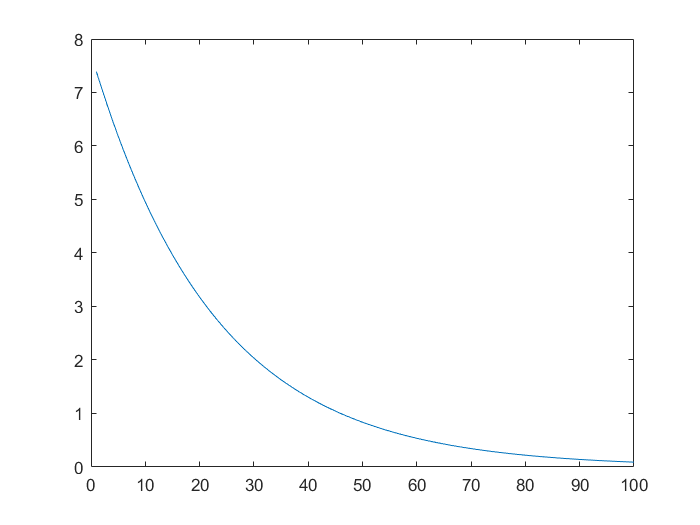

figure
slope = diff(TPR)./diff(FPR);
plot(slope)